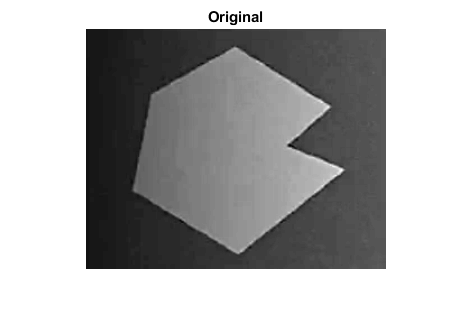

clc;clear all;close all;
image=rgb2gray(imread('thres.png'));
[r,c]=size(image);
ImageBinary=size(image);
block=50;
filter=zeros(block,block);
filteredImage=zeros(size(image));
for i=1:1:r-block
    for j=1:1:c-block
        filter(:,:)=image(i:i+block-1,j:j+block-1);
        filteredImage(i,j)=median(median(filter));
         if image(i,j)<filteredImage(i,j)
            ImageBinary(i,j)=0;
        else
            ImageBinary(i,j)=1;
        end
    end
end

imshow(image,[]);
title('Original');

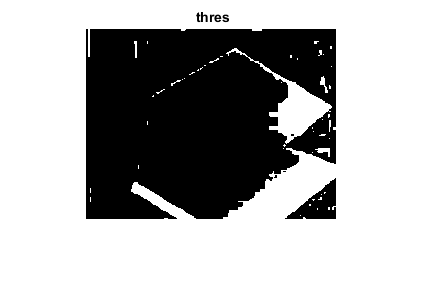

imshow((ImageBinary),[]);
title(' thres');